#### 1. Função de Transferência do sistema

a = 14.97;
s = tf('s');
Kp = 700;
Ts = 0.008; % Período de amostragem (Ts = 8ms)
Gp = a * Kp /(s+a);
Gp_zpk = zpk(Gp)

Gp_zpk =
 
    10479
  ---------
  (s+14.97)
 
Continuous-time zero/pole/gain model.
Model Properties


#### 2. Modelo em espaço de estado


$$\dot{\mathbf{x}}(t) = \mathbf{A}\mathbf{x}(t) + \mathbf{B}\mathbf{u}(t) \\
\mathbf{y}(t) = \mathbf{C}\mathbf{x}(t) + \mathbf{D}\mathbf{u}(t)
$$


[num, den] = tfdata(Gp, 'v'); 
[Ac, Bc, Cc, Dc] = tf2ss(num, den);


#### 3. Sistem em espaço de estados

sys = ss(Ac, Bc, Cc, Dc) % Sistema tempo contínuo

sys =
 
  A = 
           x1
   x1  -14.97
 
  B = 
       u1
   x1   1
 
  C = 
              x1
   y1  1.048e+04
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


#### 3.1 Resposta ao degrau

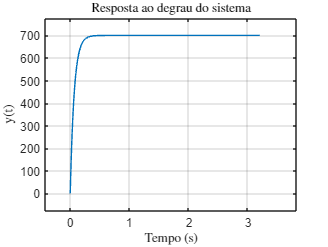

t = 0:400;
t = t*Ts;

[yp, tp] = step(sys, t);

f = figure;
plot(tp, yp);
title('Resposta ao degrau do sistema', 'Interpreter', 'latex');
ylabel('y(t)', 'Interpreter', 'latex');
xlabel('Tempo (s)', 'Interpreter', 'latex');
grid on;
exportgraphics(f, './Resultados/Sistema.pdf', 'ContentType', 'vector');

#### 4.  Projetando o Controlador

**4.1 Avaliando Controlabilidade e Observabilidade**

% Controlabilidade

Sz = Bc;

if length(Sz)==1
    if Sz~=0
        fprintf("É controlável.");
    else
        fprintf("Não é controlável.");
    end
else
    if det(Sz)~=0
        fprintf("É controlável.");
    else
        fprintf("Não é controlável.");
    end
end

É controlável.

% Convertendo para FCC

Q1_c = 1 * Sz^(-1);

Q_c = Q1_c;

Ax_fcc = Q_c*Ac*Q_c^(-1)

Ax_fcc = -14.9700

Bx_fcc = Q_c*Bc

Bx_fcc = 1

Cx_fcc = Cc*Q_c^(-1)

Cx_fcc = 10479

Sx = Bx_fcc;

P_c = Sz*Sx^(-1);

% Observabilidade

Vz = Cc;

if length(Vz)==1
    if Vz~=0
        fprintf("É observável.");
    else
        fprintf("Não é observável.");
    end
else
    if det(Vz)~=0
        fprintf("É observável.");
    else
        fprintf("Não é observável.");
    end
end

É observável.

% Convertendo para FCO

Q1_o = Cc^(-1) * 1;

Q_1_o = Q1_o;

Q_o = Q_1_o^(-1);

Ax_fco = Q_o*Ac*Q_1_o

Ax_fco = -14.9700

Bx_fco = Q_o*Bc

Bx_fco = 10479

Cx_fco = 1

Cx_fco = 1

Vx = Cx_fco;

P_o = Vz^(-1)*Vx;

**4.2 Definindo Especificações de Desempenho **

% Polos desejados
cf = 700;
cmax = 785;

% Ultrapassagem percentual.
up = ((cmax-cf)/cf) * 100 

up = 12.1429

% Tempo de acomodação.
ts = 1.5 

ts = 1.5000


qsi = (-log(up/100))/(sqrt(pi^2+log(up/100)^2));

% Calcula o fator de amortecimento
% requerido.

wn = 4/(qsi*ts); % Calcula a frequência natural
% requerida.

[numd,dend] = ord2(wn,qsi); % Produz um sistema de
% segunda ordem que atende aos
% requisitos de resposta transitória.

r = roots(dend); % Usa o denominador para
% especificar os polos dominantes.

polos = [r(1) r(2)] % Especifica a posição de todos

polos =   -2.6667 + 3.9734i  -2.6667 - 3.9734i


% os polos.

eq_caracteristica_desejada = poly(polos);

fprintf('Equação característica desejada:\n');

Equação característica desejada:


fprintf('s^2 + %.2fs + %.2f\n', ...
    eq_caracteristica_desejada(2), ...
    eq_caracteristica_desejada(3));

s^2 + 5.33s + 22.90


**4.3 Adicionando Ação Integral**

% Construção do sistema aumentado
A_hat = [Ac     zeros(size(Ac,1),1);
         -Cc     0]

A_hat = 1.0e+04 *

   -0.0015         0
   -1.0479         0



B_hat = [Bc;
         0]

B_hat =      1
     0


C_hat = [Cc 0]

C_hat =        10479           0


% Polos desejados (reutilizados ou altere para adicionar um terceiro)
% Adicionando um polo extra mais à esquerda para o integrador


% Projeto do ganho com realimentação de estados aumentados
K_hat = acker(A_hat, B_hat, polos);

% Extração dos ganhos K e Ki
K  = K_hat(1:end-1)

K = -9.6367

Ki = -K_hat(end)

Ki = 0.0022


% Sistema em malha fechada com integrador
A_hat_cl = [Ac - Bc*K, Bc*Ki;
            -Cc      ,  0];

B_hat_cl = [0; 1];  % Entrada de referência
C_hat_cl = [Cc 0];
D_hat_cl = 0;

sys_cl = ss(A_hat_cl, B_hat_cl, C_hat_cl, D_hat_cl);
sys_tf = tf(sys_cl);  % Converte espaço de estados para FT

[y, tOut] = step(sys_tf, t);

zpk(sys_tf)           % Exibe zeros, polos e ganho

ans =
 
         22.899
  ---------------------
  (s^2 + 5.333s + 22.9)
 
Continuous-time zero/pole/gain model.
Model Properties


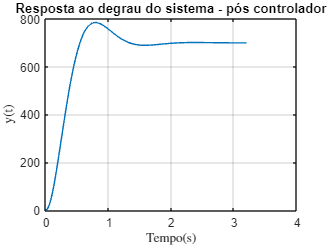


% Plotagem dos estados
f = figure;
plot(tOut, y*Kp);
title('Resposta ao degrau do sistema - pós controlador', 'Interpreter', 'latex');
ylabel('y(t)', 'Interpreter', 'latex');
xlabel('Tempo(s)','Interpreter', 'latex');
grid on;
exportgraphics(f, './Resultados/Cotrolador.pdf', 'ContentType', 'vector')

**4.4  Análise das EDS**

info = stepinfo(y, tOut);

% Tempo de acomodação a 2%
ts_pred = info.SettlingTime;
Tr = info.RiseTime;
Tp= info.PeakTime;
UP= info.Overshoot;
fprintf('Tempo de subida : %.4f ms\n', Tr);

Tempo de subida : 0.3668 ms


fprintf('Tempo de acomodação: %.4f ms\n', ts_pred);

Tempo de acomodação: 1.2233 ms


fprintf('Tempo de pico : %.4f ms\n', Tp);

Tempo de pico : 0.7920 ms


fprintf('Ultrapassagem percentual : %.4f ms\n', UP);

Ultrapassagem percentual : 12.1666 ms


### **5. Projetando o Observador**

#### **5.1 Equação caracteristica desejada do observador**

**(Ts 10x menor do que o do controlar)**

Ts_obs = (ts / 10);
wn_obs = 4/(qsi*Ts_obs); % Calcula a frequência natural

polo_o = qsi*wn_obs

polo_o = 26.6667

#### **5.2 Ganho do observador**

L = -place(Ac', Cc', polo_o)'

L = 0.0040

#### **5.3 Simulação do observador**


$$ \dot{x}(t) = A x(t) + Bu(t)\\
 \dot{\hat{x}}(t) = (A-LC) \hat{x}(t) + LC x(t) + Bu(t)$$



$$    \dot{\hat{x}} = A_o \hat{x} + B_o z \\
    y_o = C_o \hat{x}
$$
  


$$A_o =A-\textrm{LC}$$
 
$$;B_o =\left\lbrack \begin{array}{cc}
B & L
\end{array}\right\rbrack$$

$$;C_o =I_n$$

$$;z=\left\lbrack \begin{array}{c}
u\\
y
\end{array}\right\rbrack$$


o vetor z que consiste na entrada e na saída do sistema é a entrada do observador

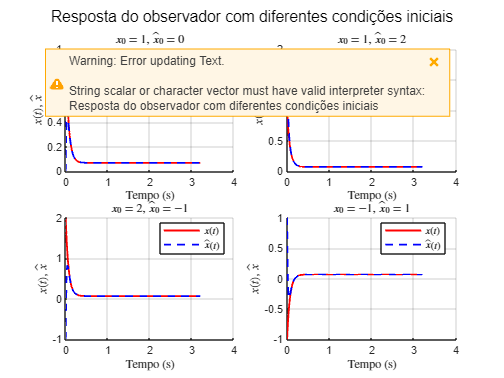

input = ones(size(t));

% Matriz do sistema e observador (1x1)
Acl = Ac - L * Cc;
Aobserver = Acl;
Bobserver = [Bc L];
Cobserver = Cc; 
Dobserver = Dc;

% Criar sistema observador
sysObserver = ss(Aobserver, Bobserver, Cobserver, Dobserver);

% Pares de condições iniciais: [x0_true, x0_obs]
init_pairs = [
    1, 0;
    1, 2;
    2, -1;
    -1, 1
];

% Figura com subplots
f = figure;
for i = 1:4
    x0true = init_pairs(i,1);
    x0obs  = init_pairs(i,2);

    % Simular sistema real
    [yTrue, timeTrue, xTrue] = lsim(sys, input, t, x0true);

    % Entrada combinada u e y para o observador
    inputUY = [input; yTrue'];

    % Simular observador
    [yObserver, timeObserver, xObserver] = lsim(sysObserver, inputUY, t, x0obs);

    % Plot
    subplot(2,2,i);
    hold on;
    plot(timeTrue, xTrue(:,1), 'r', 'LineWidth', 1.5, 'DisplayName', '$x(t)$');
    plot(timeObserver, xObserver(:,1), 'b--', 'LineWidth', 1.5, 'DisplayName', '$\hat{x}(t)$');
    title(sprintf('$x_0 = %g$, $\\hat{x}_0 = %g$', x0true, x0obs), 'Interpreter', 'latex');
    xlabel('Tempo (s)', 'Interpreter', 'latex');
    ylabel('$x(t)$, $\hat{x}$', 'Interpreter', 'latex');
    legend('Interpreter', 'latex', 'Location', 'best');
    grid on;
    hold off;
end

sgtitle('Resposta do observador com diferentes condições iniciais', 'Interpreter', 'latex');
exportgraphics(f, './Resultados/Observador.pdf', 'ContentType', 'vector');

#### 3. Discretização das equações de estado

 
$$\mathbf{x}[k+1] = \mathbf{A}_d \, \mathbf{x}[k] + \mathbf{B}_d \, \mathbf{u}[k] \\
\mathbf{y}[k] = \mathbf{C}_d \, \mathbf{x}[k]
$$


n = size(Ac);

#### Malha aberta

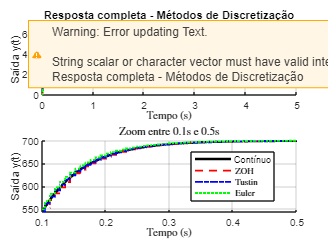

sys_zoh = c2d(sys,Ts,'zoh');
sys_tustin = c2d(sys,Ts,'tustin');

Aeuler =  eye(n) + Ts * sys.A; 
Beuler =  Ts * sys.B;
Ceuler = sys.C;
Deuler = sys.D;
sys_euler = ss(Aeuler, Beuler, Ceuler, Deuler, Ts);

t = 0:Ts:5;
u = ones(size(t)); % Degrau unitário

% Respostas dos sistemas
[y_cl, time_cl, x_cl]               = lsim(sys, u, t);       % Contínuo
[y_zoh, time_zoh, x_zoh]            = lsim(sys_zoh, u, t);      % Discretizado ZOH
[y_tustin, time_tustin, x_tustin]   = lsim(sys_tustin, u, t);   % Discretizado Tustin
[y_euler, time_euler, x_euler]      = lsim(sys_euler, u, t);    % Discretizado Euler

% Criação da figura com dois subplots
f = figure;

% --- Subplot 1: Janela de tempo completa
subplot(2,1,1);
hold on;
plot(t, y_cl,     'k-',  'LineWidth', 2,   'DisplayName', 'Contínuo');
stairs(t, y_zoh,   'r--', 'LineWidth', 1.5, 'DisplayName', 'ZOH');
stairs(t, y_tustin,'b-.', 'LineWidth', 1.5, 'DisplayName', 'Tustin');
stairs(t, y_euler, 'g:',  'LineWidth', 1.5, 'DisplayName', 'Euler');
legend('Location','best', 'Interpreter','latex');
xlabel('Tempo (s)', 'Interpreter','latex');
ylabel('Saída y(t)', 'Interpreter','latex');
title('Resposta completa - Métodos de Discretização', 'Interpreter','latex');
grid on;

% --- Subplot 2: Zoom em 0.1 a 0.5 segundos
subplot(2,1,2);
hold on;
plot(t, y_cl,     'k-',  'LineWidth', 2,   'DisplayName', 'Contínuo');
stairs(t, y_zoh,   'r--', 'LineWidth', 1.5, 'DisplayName', 'ZOH');
stairs(t, y_tustin,'b-.', 'LineWidth', 1.5, 'DisplayName', 'Tustin');
stairs(t, y_euler, 'g:',  'LineWidth', 1.5, 'DisplayName', 'Euler');
xlim([0.1 0.5]);
legend('Location','best', 'Interpreter','latex');
xlabel('Tempo (s)', 'Interpreter','latex');
ylabel('Saída y(t)', 'Interpreter','latex');
title('Zoom entre 0.1s e 0.5s', 'Interpreter','latex');
grid on;

% Exporta tudo em um único PDF
exportgraphics(f, './Resultados/Discretização.pdf', 'ContentType', 'vector');

Simulação do controlador por realimentação de estados conforme lei de controle 


$$\mathbf{x}[k+1] = \mathbf{A}_d \, \mathbf{x}[k] + \mathbf{B}_d \, \mathbf{u}[k] \\
\mathbf{y}[k] = \mathbf{C}_d \, \mathbf{x}[k]
$$
        


$$u[k] = -K \cdot x[k] + K_i \cdot x_n[k]$$


#### I. ZOH

N=400;
[y_zoh_cl, u_zoh_cl, x_zoh_cl] = ApplyController(sys_zoh, K, Ki, N, Kp, Ts);

#### II. Tustin

[y_tustin_cl, u_tustin_cl, x_tustin_cl] = ApplyController(sys_tustin, K, Ki, N, Kp, Ts);

#### III. Euler

[y_euler_cl, u_euler_cl, x_euler_cl] = ApplyController(sys_euler, K, Ki, N, Kp, Ts);

#### Resultados

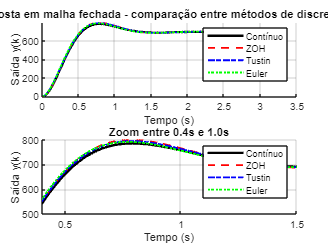

% Vetor de tempo (ajuste conforme sua simulação)
t = 0:Ts:(N-1)*Ts;
u = ones(size(t)); % Degrau unitário

[y_cl, time_cl, x_cl]               = lsim(sys_cl, u, t);       % Contínuo
f = figure;

% --- Gráfico principal ---
subplot(2,1,1);
hold on;
plot(t, y_cl * Kp,     'k-',  'LineWidth', 2,   'DisplayName', 'Contínuo');
plot(t, y_zoh_cl, 'r--', 'LineWidth', 1.5); 
plot(t, y_tustin_cl, 'b-.', 'LineWidth', 1.5);
plot(t, y_euler_cl, 'g:', 'LineWidth', 1.5);
xlabel('Tempo (s)');
ylabel('Saída y(k)');
title('Resposta em malha fechada - comparação entre métodos de discretização');
legend('Contínuo', 'ZOH', 'Tustin', 'Euler');
grid on;

% --- Zoom entre 0.1s e 0.5s ---
subplot(2,1,2);
hold on;
plot(t, y_cl * Kp,     'k-',  'LineWidth', 2,   'DisplayName', 'Contínuo');
plot(t, y_zoh_cl, 'r--', 'LineWidth', 1.5); 
plot(t, y_tustin_cl, 'b-.', 'LineWidth', 1.5);
plot(t, y_euler_cl, 'g:', 'LineWidth', 1.5);
xlabel('Tempo (s)');
ylabel('Saída y(k)');
title('Zoom entre 0.4s e 1.0s');
legend('Contínuo', 'ZOH', 'Tustin', 'Euler');
xlim([0.4 1.5]);
grid on;
% Exporta tudo em um único PDF
exportgraphics(f, './Resultados/RespostaDiscreta.pdf', 'ContentType', 'vector');

Comparacao Eds simulação


% === 1. Calcula métricas com stepinfo ===
info_cont   = stepinfo(y_cl * Kp,     t);  % contínuo com ganho Kp
info_zoh    = stepinfo(y_zoh_cl,      t);
info_tustin = stepinfo(y_tustin_cl,   t);
info_euler  = stepinfo(y_euler_cl,    t);

% === 2. Vetores da Tabela ===
Method = {
    'Contínuo';
    'ZOH';
    'Tustin';
    'Euler';
    'Referência';
};

Overshoot = [
    info_cont.Overshoot;
    info_zoh.Overshoot;
    info_tustin.Overshoot;
    info_euler.Overshoot;
    up;
];

SettlingTime = [
    info_cont.SettlingTime;
    info_zoh.SettlingTime;
    info_tustin.SettlingTime;
    info_euler.SettlingTime;
    ts;
];

% === 3. Constrói coluna com sistemas como strings A,B,C,D ===
sistemas_list = {sys, sys_zoh, sys_tustin, sys_euler};
SistemasStr = cell(5,1);

for i = 1:4
    s = sistemas_list{i};
    A_str = mat2str(s.A, 4);
    B_str = mat2str(s.B, 4);
    C_str = mat2str(s.C, 4);
    D_str = mat2str(s.D, 4);
    SistemasStr{i} = sprintf('A=%s, B=%s, C=%s, D=%s', A_str, B_str, C_str, D_str);
end

% Linha da referência
SistemasStr{5} = '—';

% === 4. Criação da Tabela Final ===
T = table(Method, SistemasStr, Overshoot, SettlingTime, ...
    'VariableNames', {'Método', 'Sistema', 'Ultrapassagem(%)', 'TempoAcomodação(s)'});

% === 5. Exibição ===
disp('== Comparação de Desempenho ==');

== Comparação de Desempenho ==


disp(T);

        Método                         Sistema                     Ultrapassagem(%)    TempoAcomodação(s)
    ______________    _________________________________________    ________________    __________________

    {'Contínuo'  }    {'A=-14.97, B=1, C=1.048e+04, D=0'      }         12.167               1.2233      
    {'ZOH'       }    {'A=0.8871, B=0.00754, C=1.048e+04, D=0'}         14.262               1.2278      
    {'Tustin'    }    {'A=0.887, B=0.007548, C=9887, D=39.55' }         13.548               1.2282      
    {'Euler'     }    {'A=0.8802, B=0.008, C=1.048e+04, D=0'  }         13.093               1.1995      
    {'Referência'}    {'—'                                    }         12.143                  1.5      



% === 6. Exportação para CSV ===
writetable(T, 'Comparacao_Desempenho.csv');

## Aplicando controlador e observador dicretizados

Sistema

    
$$\mathbf{x}[k+1] = \mathbf{A}_d  \cdot \ \mathbf{x}[k] + \mathbf{B}_d \cdot \ \mathbf{u}[k] \\
\mathbf{y}[k] = \mathbf{C}_d \cdot \mathbf{x}[k]  +  \mathbf{D}_d \, \mathbf{u}[k]
$$


Lei de controle        


$$\mathbf{u}[k] = -K \cdot \mathbf{x}[k] + K_i \cdot x_n[k]$$


Estado do integrador


$$x_n[k] = x_n[k-1] + Ts \cdot e[k-1];$$


Estado estimado pelo observador 


$$   \mathbf{{\hat{x}}}[k] = (\mathbf{A_d}- L \cdot \mathbf{C_d}) \cdot   \mathbf{{\hat{x}}}[k-1] + \mathbf{B_d}  \cdot \mathbf{u}[k-1] + L \cdot \mathbf{y}[k-1] \\
    y_o = \mathbf{C_d} \mathbf{\hat{x}}[k] + \mathbf{D_d} \cdot \mathbf{u}[k]
$$


Nova lei de controle com estado estimado


$$\mathbf{u}[k] = -K \cdot \mathbf{\hat{x}}[k] + K_i \cdot x_n[k]$$


#### I. ZOH

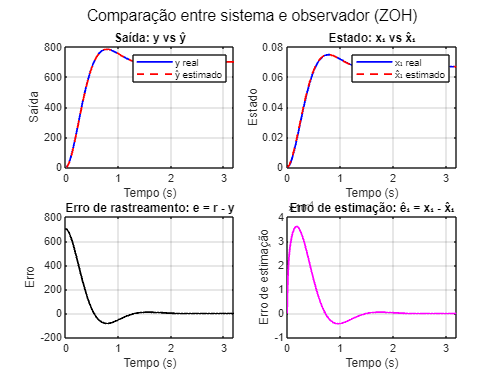

N=400;
[y_zoh, y_hat_zoh, u_zoh, x_zoh, x_hat_zoh] = ApplyControllerAndObserver(sys_zoh, K, Ki, L * Ts, N, Kp, Ts, "ZOH");

#### II. Tustin

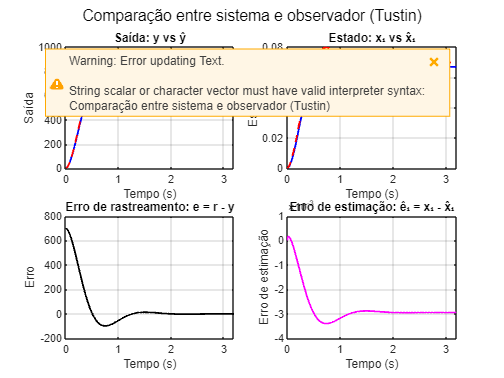

[y_tustin, y_hat_tustin, u_tustin, x_tustin, x_hat_tustin] = ApplyControllerAndObserver(sys_tustin, K, Ki, L * Ts, N, Kp, Ts, "Tustin");

#### III. Euler

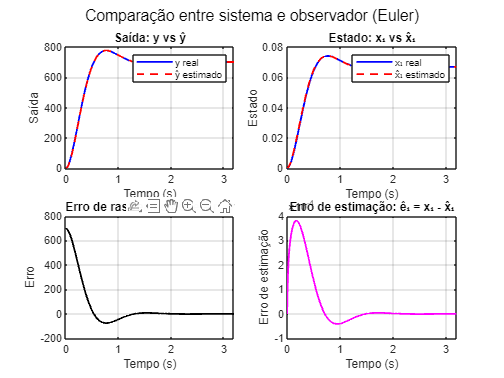

[y_euler, y_hat_euler, u_euler, x_euler, x_hat_euler] = ApplyControllerAndObserver(sys_euler, K, Ki, L * Ts, N, Kp, Ts, "Euler");